# **STEP_05:**  Explore a simple cantilever - **Discretization test**

Let's get familiar with the **Flexible Beam block** in Simscape Multibody

- [https://www.mathworks.com/help/releases/R2026a/sm/ref/flexiblerectangularbeam.html](https://www.mathworks.com/help/releases/R2026a/sm/ref/flexiblerectangularbeam.html)

And what better way, than to model and VERIFY the behavior of a simple cantilever beam 

**Objective:**

- Explore how the **number of elements used to discretize** the beam effects the computed deflection results

So here is the Cantilever system that we're going to focus on - and note the orientation of the **Inertial reference frame**.

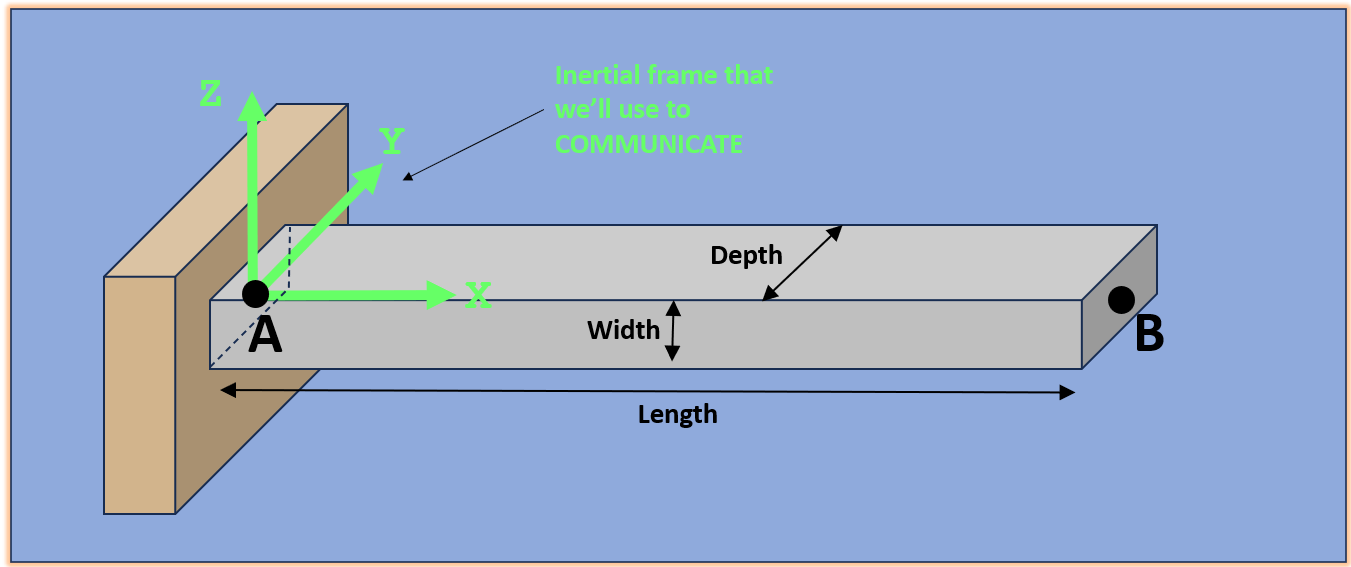

## Introduction:

The  **Flexible Beam block** in Simscape Multibody allows you to define how many Finite Elements are used to discretize the beam - as shown below:

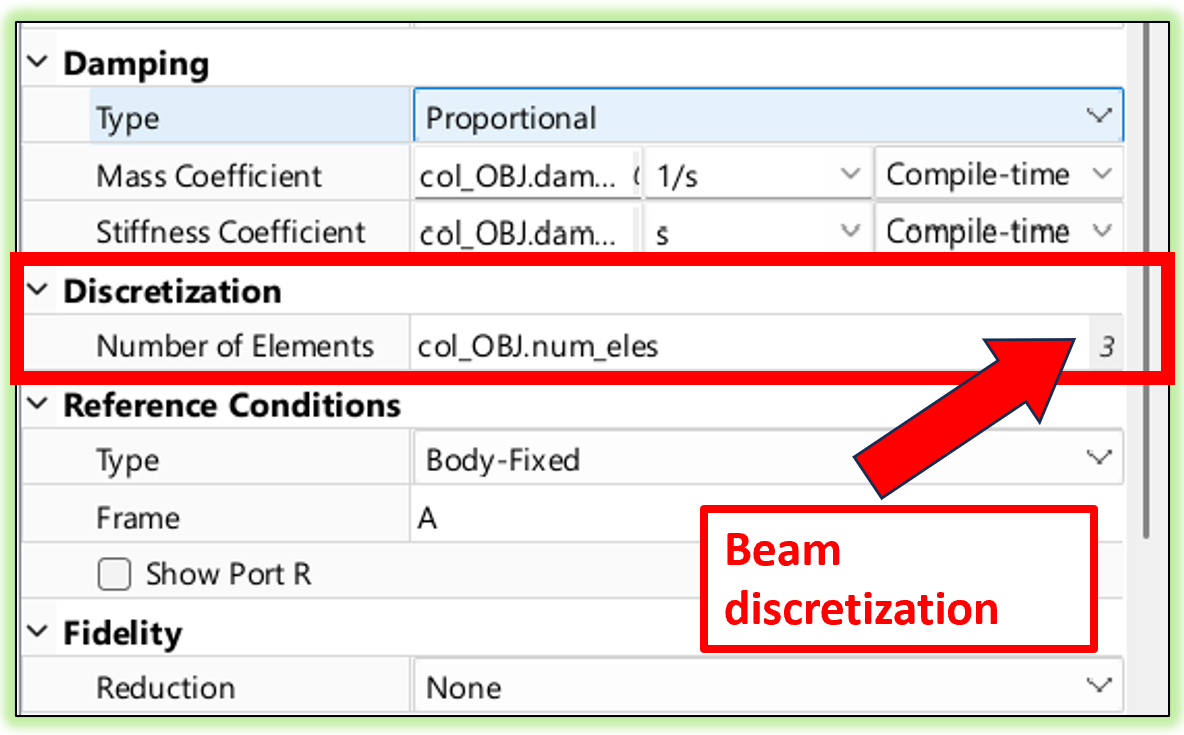

So ? - So for our simple cantilever beam, how does the number of elements impact the models response ?

In the model [`bh_cantilever_explore_discretization.slx` ](matlab:  open bh_cantilever_explore_discretization.slx)we ran a simulation of 2 cantilevers, each with a different number of elements , i.e.:

- `BEAM_A_has_1_ele` :  1 element is used to discretize the cantilever

- `BEAM_B_has_N_ele` :  6 elements are used to discretize the cantilever

 **NOTE:**  If you want to RErun this simulation .... be advised that the simulation does take a while to run.

## Clear the workspace

clear

## Define the BEAM (we'll eventually call it a COLUMN)

Define the beam's cross section.  See:

- [`bh_create_column_OBJ`](matlab:  edit  bh_create_column_OBJ)

- [`bh_flex_column_CLS`](matlab: edit bh_flex_column_CLS)

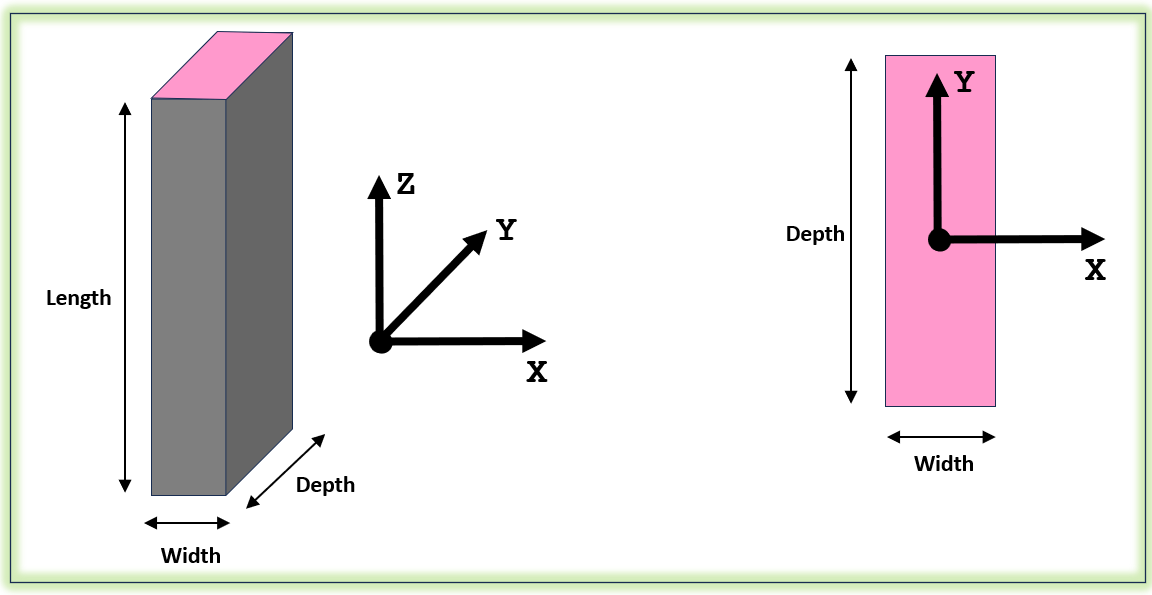

col_OBJ              = bh_create_column_OBJ(Width=1/1000, Depth=25.4/1000, Length=300/1000, density=7800);
col_OBJ.damp_ratio   = 5e-3;
% assert(0==mod(col_OBJ.num_eles,2), "###_ERROR:  pick an EVEN number of elements");

So what attributes do we have

col_OBJ

col_OBJ =   bh_flex_column_CLS with properties:

          WIDTH_x: 1.0000e-03
          DEPTH_y: 0.0254
         LENGTH_z: 0.3000
          density: 7800
      E_GPa_Young: 200
        v_Poisson: 0.3000
     damp_M_coeff: 0
     damp_K_coeff: 1.0000e-03
       damp_ratio: 0.0050
         num_eles: 1
    num_ret_modes: 5
          BC_case: "FIXED_FIXED_WITH_SWAY"
             mass: 0.0594
              vol: 7.6200e-06
               Ix: 1.3656e-09
               Iy: 2.1167e-12
               Kx: 188.1481
             area: 2.5400e-05


## Define the Environment

g_vector = [0, 0, -9.80665];

# Analyze the Simulation results

In the model [`bh_cantilever_explore_discretization.slx` ](matlab:  open bh_cantilever_explore_discretization.slx)we ran a simulation of 2 cantilevers, each with a different number of elements , i.e.:

- `BEAM_A_has_1_ele` :  1 element is used to discretize the cantilever

- `BEAM_B_has_N_ele` :  6 elements are used to discretize the cantilever

Let's explore the responses of each cantilever:

my_tab = readtable("bh_discretize_explore.xlsx");

Let's look at the time domain response after about **t=14 seconds** ... as we apply a TIP impact load at **t=15 seconds**:

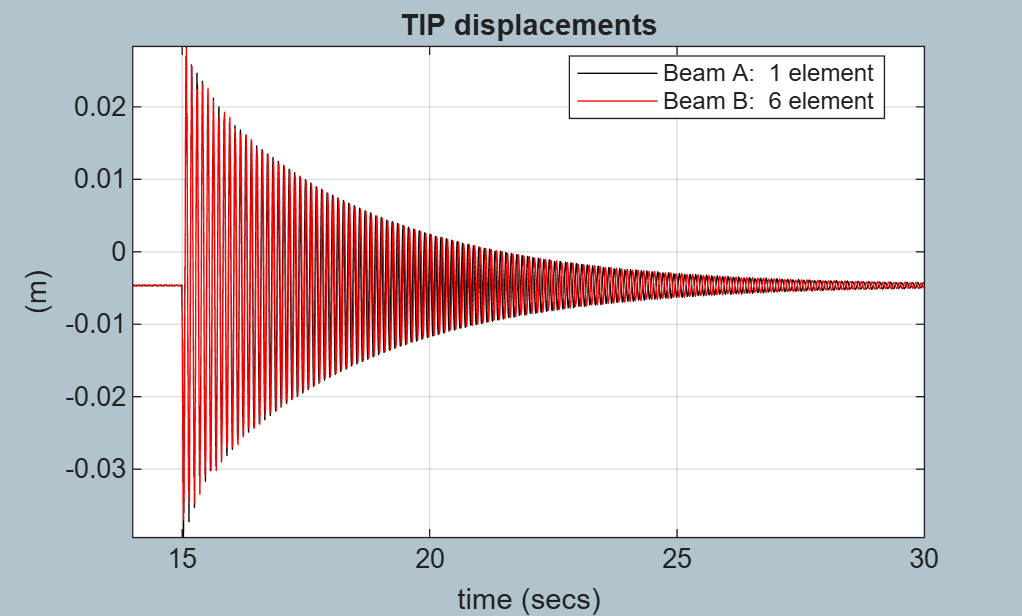

INDS = find(my_tab.time > 14 );
%INDS = find(my_tab.time > 14 & my_tab.time < 25);
figure;
    plot(my_tab.time(INDS), my_tab.ZA(INDS), "-k", DisplayName="Beam A:  1 element")
hold on
    plot(my_tab.time(INDS), my_tab.ZB(INDS), "-r", DisplayName="Beam B:  6 element")
        xlabel("time (secs)"); ylabel("(m)"); grid("on"); axis("tight")
        title("TIP displacements")
        legend("Location","best")

What about the frequency content of the 2 signals ? - Let's explore the Power spectrum of the tip responses 

dt    = diff( my_tab.time(1:2) );
Fs_Hz = 1/dt

Fs_Hz = 2000


tmp   = fft( my_tab.ZA(INDS) );
Gzz_A = tmp .* conj(tmp);

tmp   = fft( my_tab.ZB(INDS) );
Gzz_B = tmp .* conj(tmp);

fhz_list = [0:(length(Gzz_A)-1)] * 1/(length(Gzz_A) *dt );

figure;
    plot(fhz_list, 20*log10(abs(Gzz_A)), "-k", DisplayName="Beam A:  1 element")
hold on
    plot(fhz_list, 20*log10(abs(Gzz_B)), "-r", DisplayName="Beam B:  6 element")
    xlabel("Freq (Hz)"); ylabel("(dB)"); grid("on"); axis("tight")
    title("Power spectrum of TIP response")
    legend("Location","best")    
    xlim([0, 350])

Overlay the Beam Theory resonant modes

ANALYTIC_tab = bh_cantil_analytic_modes(     col_OBJ.area,        ...
                                         1e9*col_OBJ.E_GPa_Young, ...
                                             col_OBJ.Iy,          ...
                                             col_OBJ.LENGTH_z,    ...
                                             col_OBJ.density )

ANALYTIC_tab = 4×2 table
    fn_Hz     wn_radpersec
    ______    ____________

    9.0888       57.106   
    56.958       357.88   
    159.49       1002.1   
    312.53       1963.7   

	Get insights using Copilot


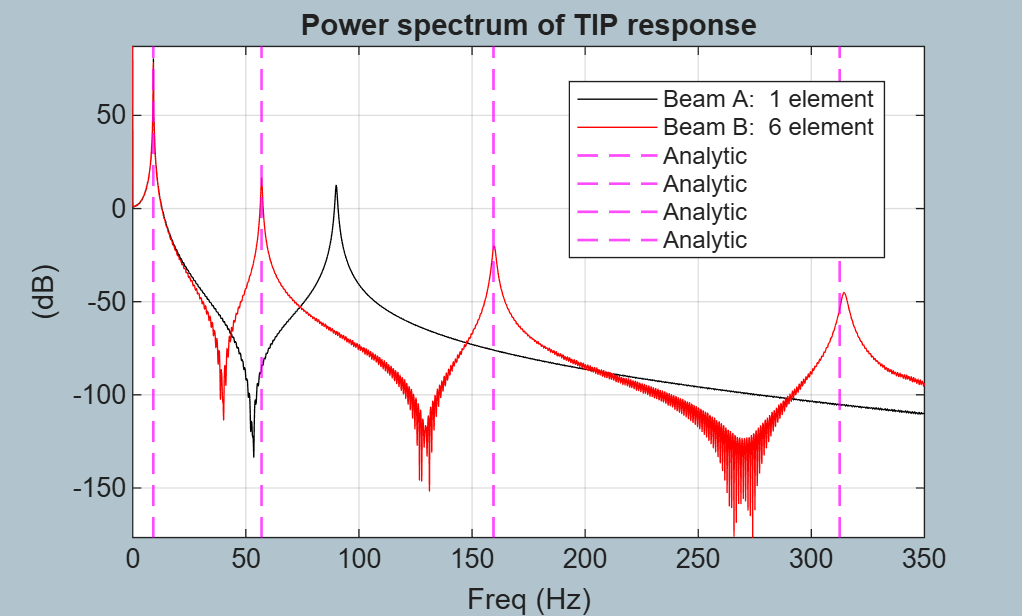


hold on
xline( ANALYTIC_tab.fn_Hz, "--m", LineWidth=1, DisplayName="Analytic" )

So ? - So yes .... if you were interested in the higher order dynamics of **this cantilever** you'd certainly need more than 1 element.

But.... as we start to use these column components to model a multi-storey building, we'll see that a low level of discretization is in fact adequate.

# Further Musings on the Cantilever

A "hand coded"implementation of a Finite Element model of a cantilever using 6-dof FRAME elements has been written in the file  [`bh_cantil_FEM_modes.mlx`](matlab:  open  bh_cantil_fem_modes.mlx).  Let's explore the undamped natural frequencies predicted by this implementation for various levels of discretization:

### Try a cantilever with 1-element:

FEM_hand_tab_1_ele = ...
    bh_cantil_FEM_modes(     col_OBJ.area,        ...
                         1e9*col_OBJ.E_GPa_Young, ...
                             col_OBJ.Iy,          ...
                             col_OBJ.LENGTH_z,    ...
                             col_OBJ.density,    ...
                             NUM_ELES=1  )

FEM_hand_tab_1_ele = 3×2 table
    fn_Hz     wn_radpersec
    ______    ____________

     9.132       57.378   
    89.975       565.33   
    4652.9        29235   

	Get insights using Copilot


 So ? - So the first 2 frequencies from this model ... coincide with the **Power spectrum peaks** produced from analyzing the times series response produced by our 1-element Simscape model. Good !

### Try a cantilever with 6-elements:

FEM_hand_tab_6_ele = ...
    bh_cantil_FEM_modes(        col_OBJ.area,        ...
                            1e9*col_OBJ.E_GPa_Young, ...
                                col_OBJ.Iy,          ...
                                col_OBJ.LENGTH_z,    ...
                                col_OBJ.density,    ...
                                NUM_ELES=6  )

FEM_hand_tab_6_ele = 18×2 table
    fn_Hz     wn_radpersec
    ______    ____________

    9.0888         57.107 
    56.972         357.97 
    159.78         1003.9 
    314.54         1976.3 
    524.39         3294.9 
    784.62         4929.9 
    1209.8         7601.5 
    1661.7          10441 
    2270.8          14268 
    3071.5          19299 
    4039.6          25382 
    4231.8          26589 
    5570.1          34998 
     12987          81597 
     22616      1.421e+05 
     33570     2.1093e+05 

	Get insights using Copilot


 So ? - So the first 4 frequencies from this model ... coincide with the **Power spectrum peaks** produced from analyzing the times series response produced by our 6-element Simscape model. Good !